# Halo Orbits in the CR3BP

addpath('/Users/gunnar/Documents/Academia/CU Boulder/RA Summer 2026/MATLAB Toolkits/cr3bp-toolkit/functions')
addpath('/Users/gunnar/Documents/Academia/CU Boulder/RA Summer 2026/MATLAB Toolkits/universal-astrodynamics-toolkit/functions/main functions')
addpath('/Users/gunnar/Documents/Academia/CU Boulder/RA Summer 2026/MATLAB Toolkits/universal-astrodynamics-toolkit/functions/other functions')
format long
set(groot, 'defaultTextInterpreter','latex', ...
'defaultLegendInterpreter','latex', ...
'defaultAxesTickLabelInterpreter','latex');

## Earth - Moon

Model introduction

EM_cr3bp = params_EM_cr3bp()

EM_cr3bp = struct with fields:
    model: [1×1 struct]
       mu: 0.012153619140872
      fun: [1×1 struct]
    scale: [1×1 struct]
      ode: [1×1 struct]


Coordinates of the Lagrange Points

L_pts_EM = lagrange_points_cr3bp(EM_cr3bp.mu)

L_pts_EM = struct with fields:
    L1: [0.836900200250094 0 0 0 0 0]
    L2: [1.155693831521116 0 0 0 0 0]
    L3: [-1.005063909707892 0 0 0 0 0]
    L4: [0.487846380859128 0.866025403784439 0 0 0 0]
    L5: [0.487846380859128 -0.866025403784439 0 0 0 0]


Ee pick a phase constraint g ( x_vec ) = y = 0:

g_i_hat = [0,1,0,0,0,0];

## Computing Halo Orbits about L1 (Howell's Method)

### Trying to compute the correction first

(i) Generate guess for initial conditions

X_0_vec = L_pts_EM.L1' + [0.01; 0; 0.01; 0; 0.001; 0]

X_0_vec =    0.846900200250094
                   0
   0.010000000000000
                   0
   0.001000000000000
                   0


(ii) Integrate until y_crossing

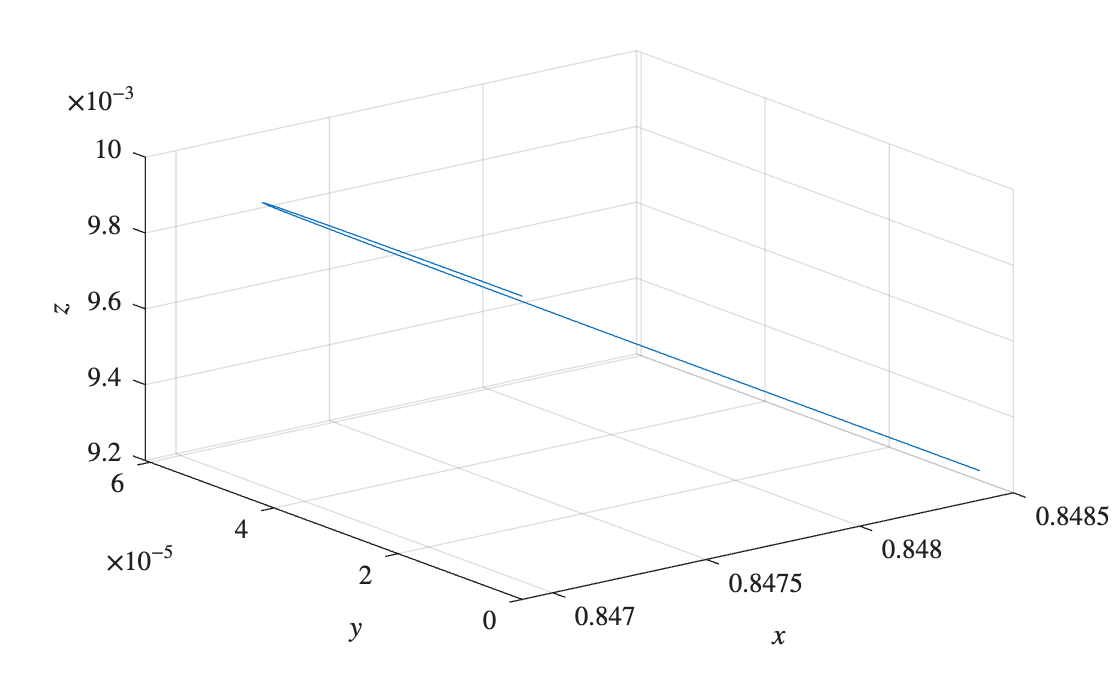

function [position,isterminal,direction] = y_0_crossing(t, X, params)
  position = X(2); % The value that we want to be zero
  isterminal = 1;  % Halt integration 
  direction = 0;   % The zero can be approached from either direction
end

[t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,10], X_0_vec, EM_cr3bp, @y_0_crossing);

figure();
plot3(X_vec_hist(:,1), X_vec_hist(:,2) , X_vec_hist(:,3));
xlabel('$x$'); ylabel('$y$'); zlabel('$z$');
grid on;

X_T_2_vec = X_vec_hist(end, :)

X_T_2_vec =    0.848390037727826  -0.000000000000000   0.009277893700333   0.019265705174771  -0.002010207126925  -0.009087004414727


T_2 = t_hist(end)

T_2 =    0.157576187284617


dXdt_T_2_vec =  eom_cr3bp(T_2, X_T_2_vec, EM_cr3bp);
Phi_T_2_mtx = squeeze(Phi_mtx_hist(end, : , :));

We see that xdot and zdot are not zero, meaning we have not found a periodic orbit yet.

(iii) Fix x_0, change z_0 and doty_0

dxdot = - X_T_2_vec(4);
ydot = X_T_2_vec(5);
dzdot = - X_T_2_vec(6);


dz0_dydot0 = ([Phi_T_2_mtx(4,3), Phi_T_2_mtx(4,5); Phi_T_2_mtx(6,3), Phi_T_2_mtx(6,5)] ...
                - (1/ydot) * [dXdt_T_2_vec(4) ; dXdt_T_2_vec(6) ] * [Phi_T_2_mtx(2,3), Phi_T_2_mtx(2,5)])...
                \ [dxdot; dzdot]

dz0_dydot0 =   -0.002814325592280
  -0.005227683090430


(iv) Change the initial conditions and start again

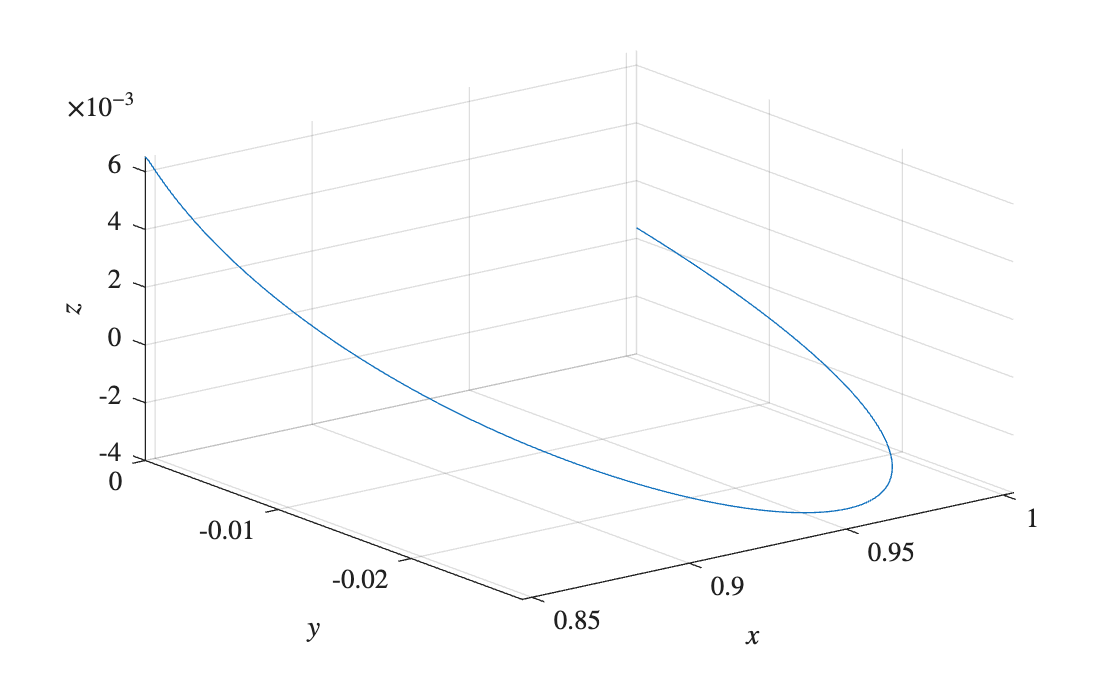

X_0_vec = X_0_vec + [0 ; 0; dz0_dydot0(1); 0; dz0_dydot0(2); 0];
[t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,10], X_0_vec, EM_cr3bp, @y_0_crossing);

figure();
plot3(X_vec_hist(:,1), X_vec_hist(:,2) , X_vec_hist(:,3));
xlabel('$x$'); ylabel('$y$'); zlabel('$z$');
grid on;

X_T_2_vec = X_vec_hist(end, :)

X_T_2_vec =    1.003203537007191   0.000000000000001   0.000368750276591   0.181809372451537   1.139971349912663   0.112636235593705


T_2 = t_hist(end)

T_2 =    0.977693743364184


dXdt_T_2_vec =  eom_cr3bp(T_2, X_T_2_vec, EM_cr3bp);
Phi_T_2_mtx = squeeze(Phi_mtx_hist(end, : , :));

### Integrating loop

%  Generate guess for initial conditions
X_0_vec = L_pts_EM.L1' + [0; 0; 0.02; 0; 0.001; 0];
iter_max = 300;
tol = 1e-10;

for i = 1 : iter_max

    % Integrate until y_crossing
    [t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,10], X_0_vec, EM_cr3bp, @y_0_crossing);
    
    % Store values at t = T/2
    X_T_2_vec = X_vec_hist(end, :);
    T_2 = t_hist(end);
    dXdt_T_2_vec =  eom_cr3bp(T_2, X_T_2_vec, EM_cr3bp);
    Phi_T_2_mtx = squeeze(Phi_mtx_hist(end, : , :));

    % Check if it is a periodic orbit
    
    if abs(X_T_2_vec(4)) < tol && abs(X_T_2_vec(6)) < tol
        X_H_0_vec = X_0_vec;
        T_H = 2*T_2;
        break
    end

    % % Fix x_0, change z_0 and doty_0
    % dxdot = - X_T_2_vec(4);
    % ydot = X_T_2_vec(5);
    % dzdot = - X_T_2_vec(6);
    % 
    % % Find corrections in the initial conditions
    % dz0_dydot0 = ([Phi_T_2_mtx(4,3), Phi_T_2_mtx(4,5); Phi_T_2_mtx(6,3), Phi_T_2_mtx(6,5)] ...
    %                 - (1/ydot) * [dXdt_T_2_vec(4) ; dXdt_T_2_vec(6) ] * [Phi_T_2_mtx(2,3), Phi_T_2_mtx(2,5)])...
    %                 \ [dxdot; dzdot];
    % 
    % % Change the initial conditions and start again
    % X_0_vec = X_0_vec + [0 ; 0; dz0_dydot0(1); 0; dz0_dydot0(2); 0];

    % Fix z_0, change x_0 and doty_0
    dxdot = - X_T_2_vec(4);
    ydot = X_T_2_vec(5);
    dzdot = - X_T_2_vec(6);

    % Find corrections in the initial conditions
    dx0_dydot0 = ([Phi_T_2_mtx(4,1), Phi_T_2_mtx(4,5); Phi_T_2_mtx(6,1), Phi_T_2_mtx(6,5)] ...
                    - (1/ydot) * [dXdt_T_2_vec(4) ; dXdt_T_2_vec(6) ] * [Phi_T_2_mtx(2,1), Phi_T_2_mtx(2,5)])...
                    \ [dxdot; dzdot];

    % Change the initial conditions and start again
    X_0_vec = X_0_vec + [dx0_dydot0(1) ; 0; 0; 0; dx0_dydot0(2); 0];

end
i

i =     11


Integrate the whole halo orbit

X_H_0_vec - L_pts_EM.L1'

ans =   -0.013534318801164
                   0
   0.020000000000000
                   0
   0.132730232822014
                   0


 X_H_0_vec

X_H_0_vec =    0.823365881448930
                   0
   0.020000000000000
                   0
   0.132730232822014
                   0


 T_H

T_H =    2.745672052473394


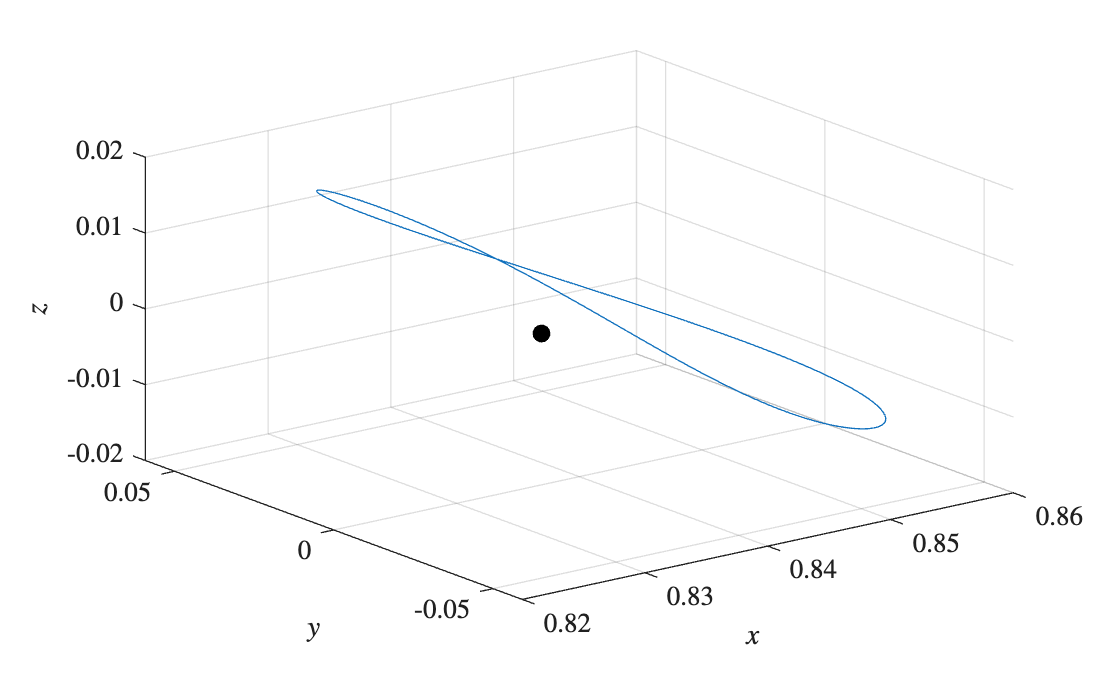

[t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,T_H], X_H_0_vec, EM_cr3bp);

figure();
plot3(X_vec_hist(:,1), X_vec_hist(:,2) , X_vec_hist(:,3)); hold on;
plot(L_pts_EM.L1(1), L_pts_EM.L1(2), 'k.', 'MarkerSize', 20, 'DisplayName', sprintf('$L_1$')); hold on;
xlabel('$x$'); ylabel('$y$'); zlabel('$z$');
grid on;

X_vec_hist(1,:) - X_vec_hist(end,:)

ans = 1.0e-11 *

  -0.052835513741911   0.018518472218907   0.001626823675771  -0.142148201728587   0.058927862589542   0.009655459713309


Plotting multiple halo orbits about L1

z_H_0_list = [0.01, 0.016, 0.02, 0.042, 0.045]

z_H_0_list =    0.010000000000000   0.016000000000000   0.020000000000000   0.042000000000000   0.045000000000000


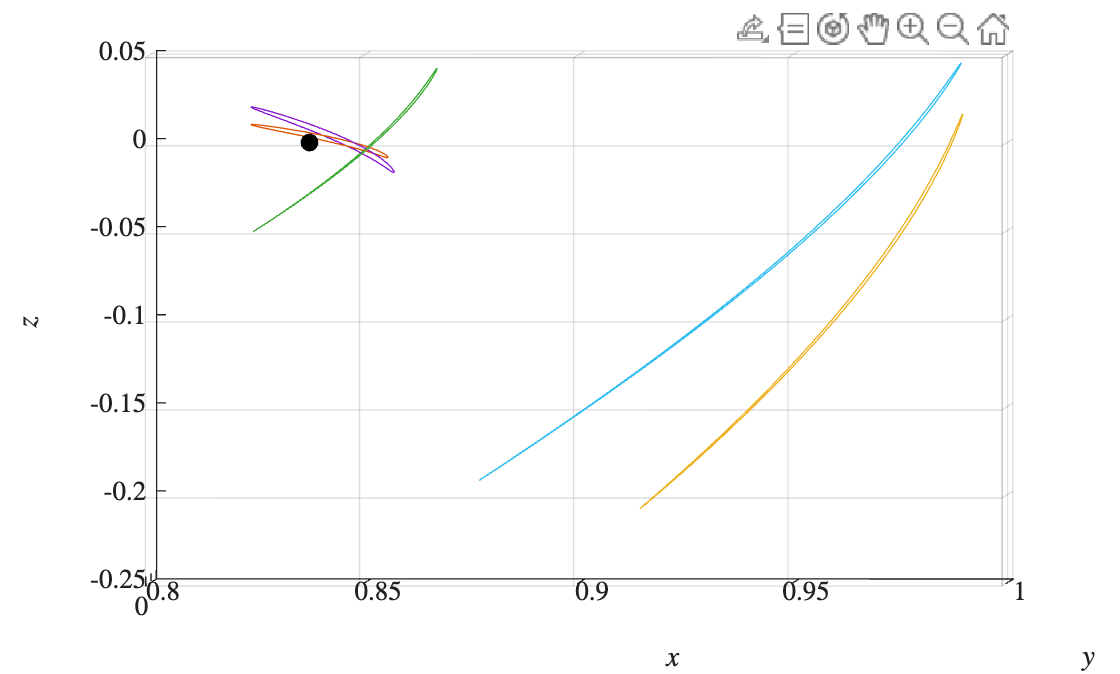

T_H =    2.743651432475551


T_H =    1.825168779832651


T_H =    2.745672052473394


T_H =    2.758952927583206


T_H =    2.169275026541577


figure();
plot3(L_pts_EM.L1(1), L_pts_EM.L1(2), L_pts_EM.L1(3) ,  'k.', 'MarkerSize', 20, 'DisplayName', sprintf('$L_1$')); hold on;
xlabel('$x$'); ylabel('$y$'); zlabel('$z$');
grid on;

for z_0 = z_H_0_list

    % Find IC for Halo orbit
    X_0_vec = L_pts_EM.L1' + [0; 0; z_0; 0; 0.001; 0];
    iter_max = 300;
    tol = 1e-10;
    
    for i = 1 : iter_max
    
        % Integrate until y_crossing
        [t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,10], X_0_vec, EM_cr3bp, @y_0_crossing);
        
        % Store values at t = T/2
        X_T_2_vec = X_vec_hist(end, :);
        T_2 = t_hist(end);
        dXdt_T_2_vec =  eom_cr3bp(T_2, X_T_2_vec, EM_cr3bp);
        Phi_T_2_mtx = squeeze(Phi_mtx_hist(end, : , :));
    
        % Check if it is a periodic orbit
        if abs(X_T_2_vec(4)) < tol && abs(X_T_2_vec(6)) < tol
            X_H_0_vec = X_0_vec;
            T_H = 2*T_2
            break
        end
    
        % Fix z_0, change x_0 and doty_0
        dxdot = - X_T_2_vec(4);
        ydot = X_T_2_vec(5);
        dzdot = - X_T_2_vec(6);
    
        % Find corrections in the initial conditions
        dx0_dydot0 = ([Phi_T_2_mtx(4,1), Phi_T_2_mtx(4,5); Phi_T_2_mtx(6,1), Phi_T_2_mtx(6,5)] ...
                        - (1/ydot) * [dXdt_T_2_vec(4) ; dXdt_T_2_vec(6) ] * [Phi_T_2_mtx(2,1), Phi_T_2_mtx(2,5)])...
                        \ [dxdot; dzdot];
    
        % Change the initial conditions and start again
        X_0_vec = X_0_vec + [dx0_dydot0(1) ; 0; 0; 0; dx0_dydot0(2); 0];
    
    end

    % Integrate whole halo orbit
    [t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,T_H], X_H_0_vec, EM_cr3bp);
    plot3(X_vec_hist(:,1), X_vec_hist(:,2) , X_vec_hist(:,3)); hold on;
end

### Weird Orbit Found

%  Generate guess for initial conditions
X_0_vec = L_pts_EM.L2' + [0; 0; 0.041; 0; 0.001; 0];
iter_max = 300;
tol = 1e-10;

for i = 1 : iter_max

    % Integrate until y_crossing
    [t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,10], X_0_vec, EM_cr3bp, @y_0_crossing);
    
    % Store values at t = T/2
    X_T_2_vec = X_vec_hist(end, :);
    T_2 = t_hist(end);
    dXdt_T_2_vec =  eom_cr3bp(T_2, X_T_2_vec, EM_cr3bp);
    Phi_T_2_mtx = squeeze(Phi_mtx_hist(end, : , :));

    % Check if it is a periodic orbit
    
    if abs(X_T_2_vec(4)) < tol && abs(X_T_2_vec(6)) < tol
        X_H_0_vec = X_0_vec;
        T_H = 2*T_2;
        break
    end

    % Fix z_0, change x_0 and doty_0
    dxdot = - X_T_2_vec(4);
    ydot = X_T_2_vec(5);
    dzdot = - X_T_2_vec(6);

    % Find corrections in the initial conditions
    dx0_dydot0 = ([Phi_T_2_mtx(4,1), Phi_T_2_mtx(4,5); Phi_T_2_mtx(6,1), Phi_T_2_mtx(6,5)] ...
                    - (1/ydot) * [dXdt_T_2_vec(4) ; dXdt_T_2_vec(6) ] * [Phi_T_2_mtx(2,1), Phi_T_2_mtx(2,5)])...
                    \ [dxdot; dzdot];

    % Change the initial conditions and start again
    X_0_vec = X_0_vec + [dx0_dydot0(1) ; 0; 0; 0; dx0_dydot0(2); 0];

end
i

i =     10


Integrate the whole halo orbit

X_H_0_vec - L_pts_EM.L2'

ans =    0.262746764809334
                   0
   0.041000000000000
                   0
  -0.711186804527914
                   0


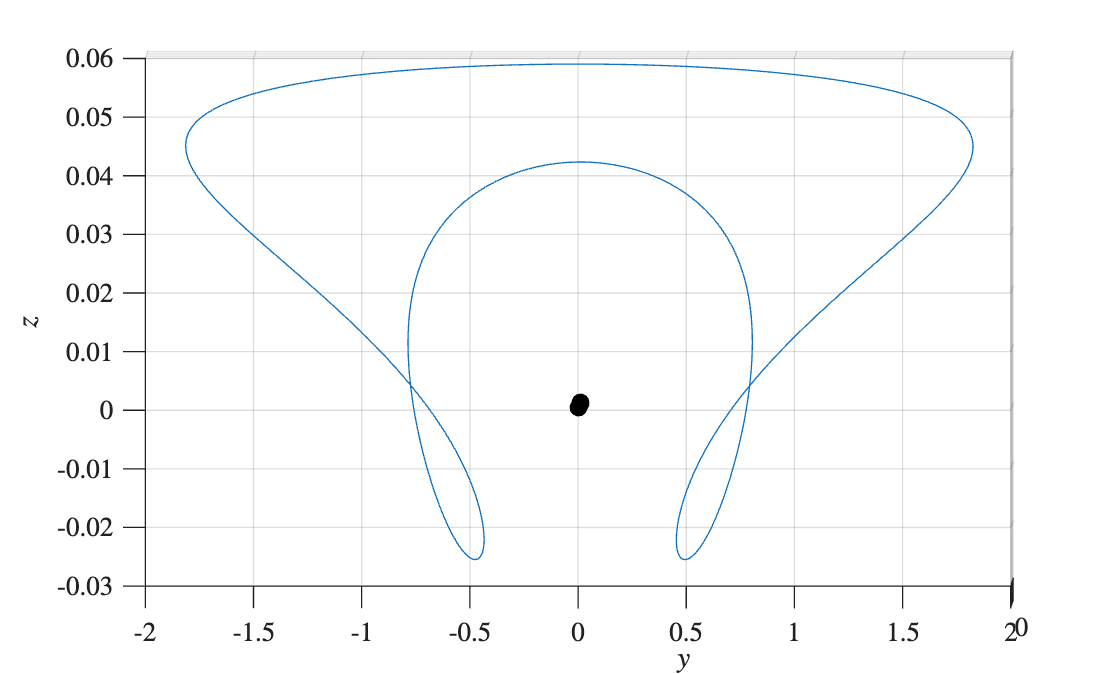

[t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,T_H], X_H_0_vec, EM_cr3bp);

figure();
plot3(X_vec_hist(:,1), X_vec_hist(:,2) , X_vec_hist(:,3)); hold on;
plot3(L_pts_EM.L2(1), L_pts_EM.L2(2), L_pts_EM.L2(3), 'k.', 'MarkerSize', 20, 'DisplayName', sprintf('$L_2$')); hold on;
plot3(L_pts_EM.L3(1), L_pts_EM.L3(2), L_pts_EM.L3(3), 'k.', 'MarkerSize', 20, 'DisplayName', sprintf('$L_2$')); hold on;
plot3(L_pts_EM.L1(1), L_pts_EM.L1(2), L_pts_EM.L1(3), 'k.', 'MarkerSize', 20, 'DisplayName', sprintf('$L_1$')); hold on;
xlabel('$x$'); ylabel('$y$'); zlabel('$z$');
grid on;

X_vec_hist(1,:) - X_vec_hist(end,:)

ans = 1.0e-08 *

   0.046877546289181  -0.131898276305473   0.001017586015450  -0.061002451252509  -0.057429250244212   0.002255869240414


### Computing Halo Orbits about L2

%  Generate guess for initial conditions
X_0_vec = L_pts_EM.L1' + [0; 0; 0.036; 0; 0.001; 0];
iter_max = 300;
tol = 1e-10;

for i = 1 : iter_max

    % Integrate until y_crossing
    [t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,10], X_0_vec, EM_cr3bp, @y_0_crossing);
    
    % Store values at t = T/2
    X_T_2_vec = X_vec_hist(end, :);
    T_2 = t_hist(end);
    dXdt_T_2_vec =  eom_cr3bp(T_2, X_T_2_vec, EM_cr3bp);
    Phi_T_2_mtx = squeeze(Phi_mtx_hist(end, : , :));

    % Check if it is a periodic orbit
    
    if abs(X_T_2_vec(4)) < tol && abs(X_T_2_vec(6)) < tol
        X_H_0_vec = X_0_vec;
        T_H = 2*T_2;
        break
    end

    % Fix z_0, change x_0 and doty_0
    dxdot = - X_T_2_vec(4);
    ydot = X_T_2_vec(5);
    dzdot = - X_T_2_vec(6);

    % Find corrections in the initial conditions
    dx0_dydot0 = ([Phi_T_2_mtx(4,1), Phi_T_2_mtx(4,5); Phi_T_2_mtx(6,1), Phi_T_2_mtx(6,5)] ...
                    - (1/ydot) * [dXdt_T_2_vec(4) ; dXdt_T_2_vec(6) ] * [Phi_T_2_mtx(2,1), Phi_T_2_mtx(2,5)])...
                    \ [dxdot; dzdot];

    % Change the initial conditions and start again
    X_0_vec = X_0_vec + [dx0_dydot0(1) ; 0; 0; 0; dx0_dydot0(2); 0];

end
i

i =     13


Integrate the whole halo orbit

X_H_0_vec - L_pts_EM.L2'

ans =    0.023894480948572
                   0
   0.036000000000000
                   0
  -0.162952261622640
                   0


X_H_0_vec

X_H_0_vec =    1.179588312469689
                   0
   0.036000000000000
                   0
  -0.162952261622640
                   0


T_H

T_H =    3.404910824920741


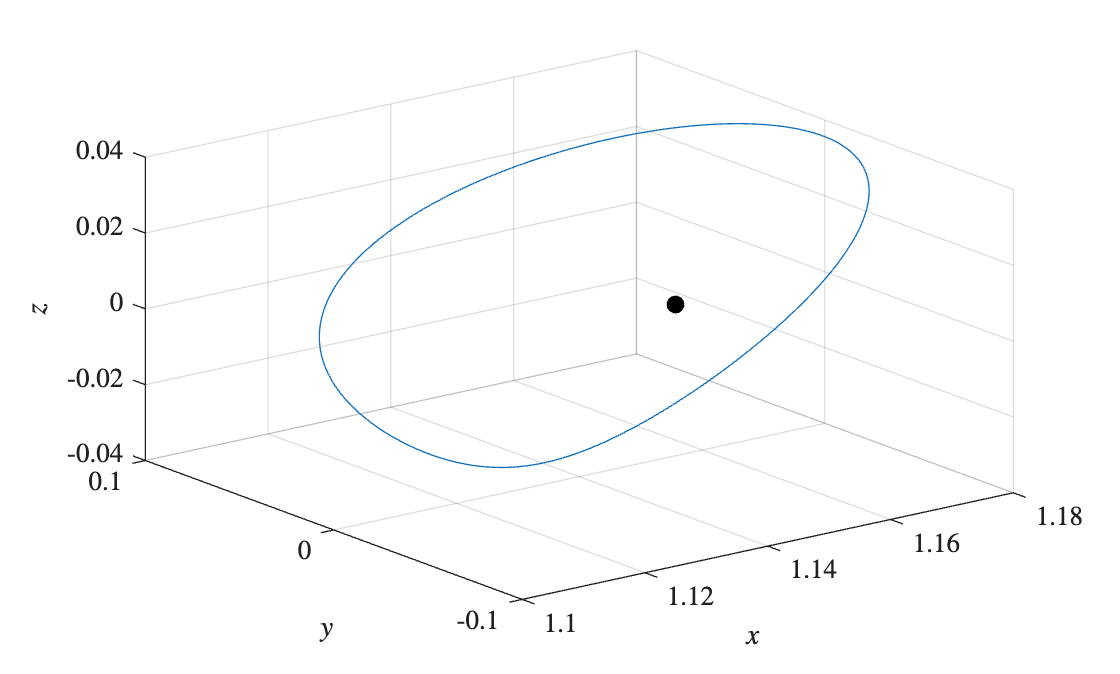

[t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,T_H], X_H_0_vec, EM_cr3bp);

figure();
plot3(X_vec_hist(:,1), X_vec_hist(:,2) , X_vec_hist(:,3)); hold on;
plot3(L_pts_EM.L2(1), L_pts_EM.L2(2), L_pts_EM.L2(3), 'k.', 'MarkerSize', 20, 'DisplayName', sprintf('$L_2$')); hold on;
xlabel('$x$'); ylabel('$y$'); zlabel('$z$');
grid on;

X_vec_hist(1,:) - X_vec_hist(end,:)

ans = 1.0e-09 *

  -0.106334052674129   0.041994638907823  -0.007353888331618  -0.192233634099714   0.108075798310736  -0.032166939007361


### Computing Halo Orbits about L3

%  Generate guess for initial conditions
X_0_vec = L_pts_EM.L3' + [0.01; 0; 0.025; 0; 0.001; 0];
iter_max = 300;
tol = 1e-10;

for i = 1 : iter_max

    % Integrate until y_crossing
    [t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,10], X_0_vec, EM_cr3bp, @y_0_crossing);
    
    % Store values at t = T/2
    X_T_2_vec = X_vec_hist(end, :);
    T_2 = t_hist(end);
    dXdt_T_2_vec =  eom_cr3bp(T_2, X_T_2_vec, EM_cr3bp);
    Phi_T_2_mtx = squeeze(Phi_mtx_hist(end, : , :));

    % Check if it is a periodic orbit
    if abs(X_T_2_vec(4)) < tol && abs(X_T_2_vec(6)) < tol
        X_H_0_vec = X_0_vec;
        T_H = 2*T_2;
        break
    end

    % Fix z_0, change x_0 and doty_0
    dxdot = - X_T_2_vec(4);
    ydot = X_T_2_vec(5);
    dzdot = - X_T_2_vec(6);

    % Find corrections in the initial conditions
    dx0_dydot0 = ([Phi_T_2_mtx(4,1), Phi_T_2_mtx(4,5); Phi_T_2_mtx(6,1), Phi_T_2_mtx(6,5)] ...
                    - (1/ydot) * [dXdt_T_2_vec(4) ; dXdt_T_2_vec(6) ] * [Phi_T_2_mtx(2,1), Phi_T_2_mtx(2,5)])...
                    \ [dxdot; dzdot];

    % Change the initial conditions and start again
    X_0_vec = X_0_vec + [dx0_dydot0(1) ; 0; 0; 0; dx0_dydot0(2); 0];
end
i

i =      9


Integrate the whole halo orbit

X_H_0_vec - L_pts_EM.L2'

ans =   -2.852293350982941
                   0
   0.025000000000000
                   0
   1.279445663804792
                   0


X_H_0_vec

X_H_0_vec =   -1.696599519461825
                   0
   0.025000000000000
                   0
   1.279445663804792
                   0


T_H

T_H =    6.239134209697106


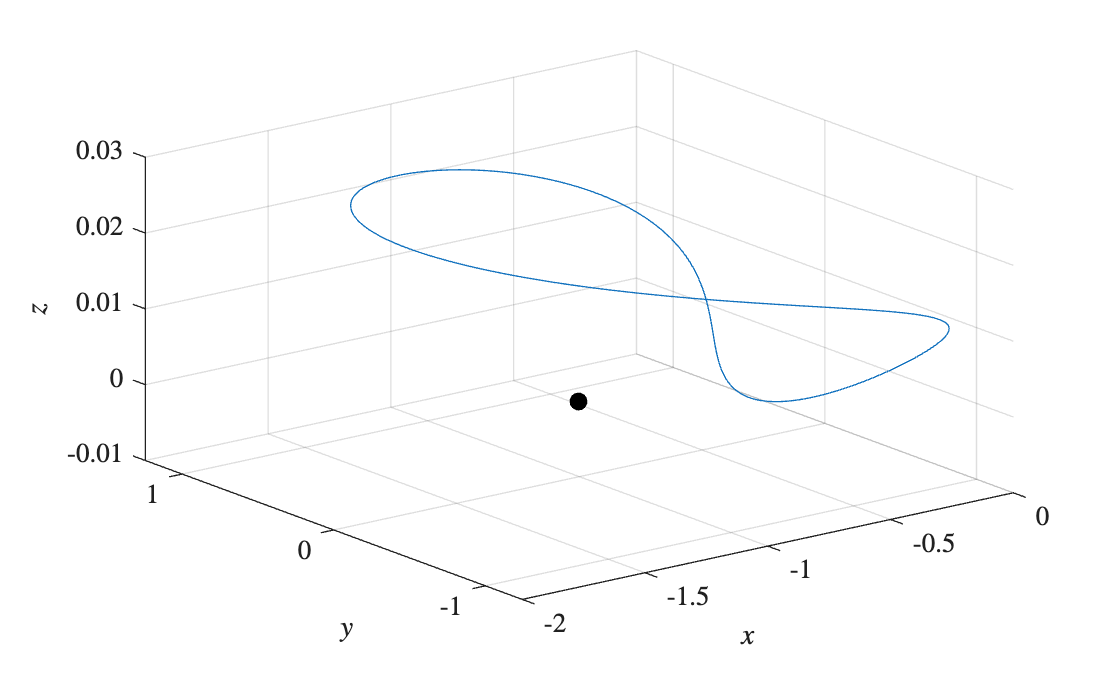

[t_hist, X_vec_hist, Phi_mtx_hist, i_e, t_e, x_e_vec, Phi_mtx_e] = integrate_cr3bp([0,T_H], X_H_0_vec, EM_cr3bp);

figure();
plot3(X_vec_hist(:,1), X_vec_hist(:,2) , X_vec_hist(:,3)); hold on;
plot3(L_pts_EM.L3(1), L_pts_EM.L3(2), L_pts_EM.L3(3), 'k.', 'MarkerSize', 20, 'DisplayName', sprintf('$L_2$')); hold on;
xlabel('$x$'); ylabel('$y$'); zlabel('$z$');
grid on;

X_vec_hist(1,:) - X_vec_hist(end,:)

ans = 1.0e-11 *

  -0.179611880923858   0.067610574239487   0.002505981533396  -0.056756199981871   0.221045404202869   0.001838853488415
